# Cycling

Consolidate several recordings of the position into one ride table

files = dir("/MATLAB Drive/MobileSensorData/*.mat")

ride = table();

files = 4x1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


for i = 1:size(files,1)
    load([files(i).folder,'/',files(i).name])
    ride = [Position;ride];
end
Position = ride

clf

Position = 3611x6 timetable
           Timestamp            latitude    longitude    altitude    speed    course    hacc
    ________________________    ________    _________    ________    _____    ______    ____

    21-Jun-2025 17:48:16.000     42.372      -71.292      20.837        0         0     3.79
    21-Jun-2025 17:48:17.000     42.372      -71.292      21.147        0         0     3.79
    21-Jun-2025 17:48:18.000     42.372      -71.292      20.827        0         0     3.79
    21-Jun-2025 17:48:19.000     42.372      -71.292      21.138        0         0     3.79
    21-Jun-2025 17:48:20.000     42.372      -71.292       20.62        0         0     3.

% Create figure
fig = figure('Color', 'w');
% Create geoaxes and fill entire figure
gax = geoaxes(fig, 'Position', [0 0 1 1]);
% geobasemap(gax, 'streets')  % or 'topographic', 'satellite', etc.
geoscatter(Position.latitude,Position.longitude,60,Position.speed,"filled")
% colormap turbo
clim([min(speed), max(speed)])
colorbar('off')
% Set map view to cover the whole route
geolimits([min(lat)-0.001, max(lat)+0.001], [min(lon)-0.001, max(lon)+0.001])
% save to png
saveas(gcf, 'ride_map.png');

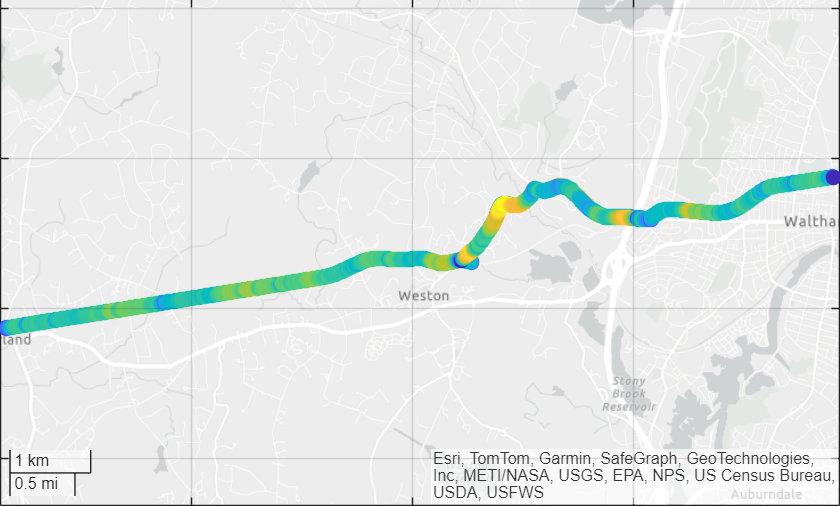

duration = Position.Timestamp(end)-Position.Timestamp(1)

meanspeed = mean(Position.speed) % m/s

duration = duration
   01:08:07


meanspeedkmh = meanspeed * 3.6

meanspeed = 6.1967

% Calculate the total distance traveled using the haversine formula
distance = 0;

meanspeedkmh = 22.3082

for j = 1:length(lat)-1
    distance = distance + haversine(lat(j), lon(j), lat(j+1), lon(j+1));
end
distance

Animate (limited to 1000 frames)

clf

distance = 2.2514e+04

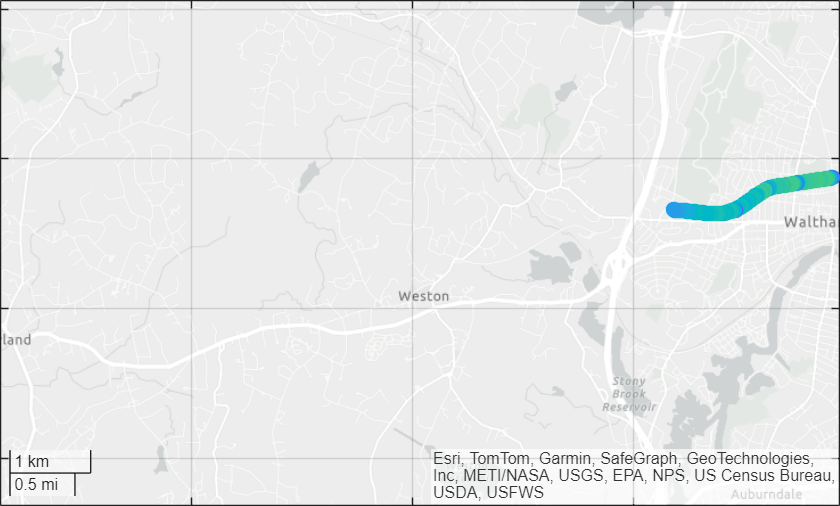

% Extract variables
lat = Position.latitude;
lon = Position.longitude;
speed = Position.speed;
time = Position.Timestamp;
% Create figure
fig = figure('Color', 'w');

% Create geoaxes and fill entire figure
gax = geoaxes(fig, 'Position', [0 0 1 1]);
% geobasemap(gax, 'streets')  % or 'topographic', 'satellite', etc.
hold(gax, 'on')

% Initial trail plot
trail = geoscatter(lat(1), lon(1), 60, speed(1), 'filled'); % trail of the path

% colormap turbo
clim([min(speed), max(speed)])
colorbar('off')
hold(gax,'off')

% Set map view to cover the whole route
geolimits([min(lat)-0.001, max(lat)+0.001], [min(lon)-0.001, max(lon)+0.001])

% Animation loop, only every 4th frame
for k = 1:4:length(lat)
    set(trail, ...
        'LatitudeData', lat(1:k), ...
        'LongitudeData', lon(1:k), ...
        'CData', speed(1:k));  % color by speed
    
    % title(string(time(k)), 'FontSize', 14)
    drawnow
    
    % % Optional: pause based on time delta (real time simulation)
    % if k > 1
    %     dt = seconds(time(k) - time(k-1));
    %     pause(dt);  % sampling is every second
    % end
end

Animate a part of the ride (third recording)

load("/MATLAB Drive/MobileSensorData/sensorlog_20250621_173108.mat")
% lat = 42.3721;lon = -71.3001;
i = 796;

% Extract variables
lat = Position.latitude;
lon = Position.longitude;
speed = Position.speed;
time = Position.Timestamp;
% Create figure
fig = figure('Color', 'w');

% Create geoaxes and fill entire figure
gax = geoaxes(fig, 'Position', [0 0 1 1]);
% geobasemap(gax, 'streets')  % or 'topographic', 'satellite', etc.
hold(gax, 'on')

% Initial trail plot
trail = geoscatter(lat(1:i), lon(1:i), 60, speed(1:i), 'filled'); % trail of the path

% colormap turbo
clim([min(speed), max(speed)])
colorbar('off')
% hold(gax,'off')

% Set map view to cover the whole route
geolimits([min(lat)-0.001, max(lat)+0.001], [min(lon)-0.001, max(lon)+0.001])

% Animation loop
for k = i:length(lat)
    set(trail, ...
        'LatitudeData', lat(1:k), ...
        'LongitudeData', lon(1:k), ...
        'CData', speed(1:k));  % color by speed
    
    % title(string(time(k)), 'FontSize', 14)
    drawnow
    
    % % Optional: pause based on time delta (real time simulation)
    % if k > 1
    %     dt = seconds(time(k) - time(k-1));
    %     pause(dt);  % sampling is every second
    % end
end

Helpers

function d = haversine(lat1, lon1, lat2, lon2, R)
% HAVERSINE  Great‐circle distance between points on a sphere
%
%   d = HAVERSINE(lat1, lon1, lat2, lon2) returns the distance (in meters)
%   between points (lat1,lon1) and (lat2,lon2), specified in decimal degrees,
%   assuming a spherical Earth of radius R = 6371000 m.
%
%   d = HAVERSINE(lat1, lon1, lat2, lon2, R) lets you specify a different
%   radius R (same units as the output d).

    if nargin<5
        R = 6371000;  % mean Earth radius in meters
    end

    % Convert degrees to radians
    toRad = @(x) x .* (pi/180);
    phi1 = toRad(lat1);
    phi2 = toRad(lat2);
    deltaphi = toRad(lat2 - lat1);
    deltalambda = toRad(lon2 - lon1);

    % Haversine formula
    a = sin(deltaphi/2).^2 + cos(phi1) .* cos(phi2) .* sin(deltalambda/2).^2;
    c = 2 .* atan2( sqrt(a), sqrt(1 - a) );

    d = R .* c;
end